# **Computer Vision (CZ4003) - Lab 2 **

## Part 1: EDGE DETECTION

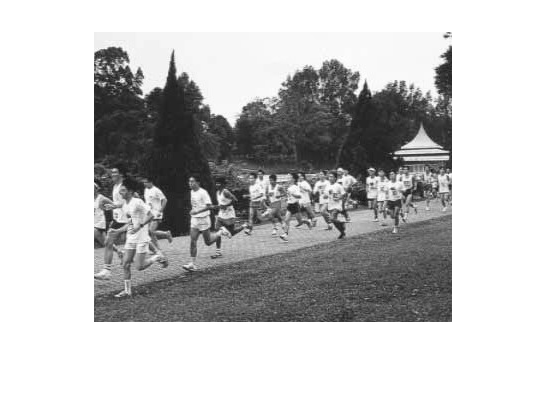

% Part A: Read in image
P = imread('images/maccropped.jpg');
I = rgb2gray(P);
imshow(I);

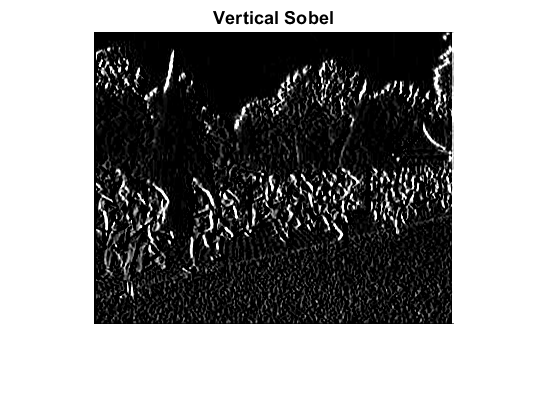

% Part B: Sobel filtering
sobel_v = [
    -1 0 1; 
    -2 0 2; 
    -1 0 1;
];
sobel_h = [
    -1 -2 -1; 
    0 0 0; 
    1 2 1;
];

res1 = conv2(I, sobel_v);
imshow(uint8(res1)), title("Vertical Sobel");

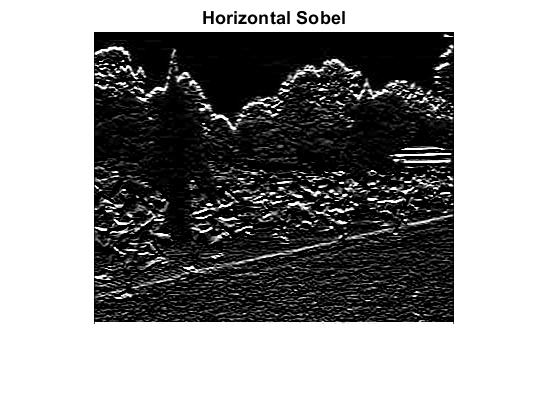

res2 = conv2(I, sobel_h); 
imshow(uint8(res2)), title("Horizontal Sobel");

Since sobel kernel is designed to identify gradient along one specific direction (**x** and **y** in this case), region with diagnal gradient will appear with **low intensity, or invisible** in the resultant images. 

For the intuition behind Sobel, it's a simple** gradient **operator $[-{1\over{2}},\ 0,\ {1\over{2}}]$ combined with a shortest non-trivial **Pascal/Gaussian smoothing** $[{1\over{4}},\ {1\over{2}},\ {1\over{4}}]^T$, this however will not be affect if the global scale factor are normalized. Thus the product of 2 operations give a 3x3 filter. Notice that elements of Sobel filters are **dyadic numbers** so it's efficient when dealing with binary operations (less round-off error, robust to bit shifts, etc).

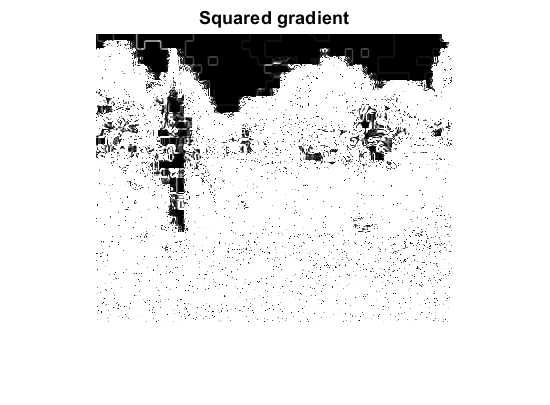

% part C: Get total Gradient
E = res1.^2 + res2.^2; 
imshow(uint8(E)), title("Squared gradient");

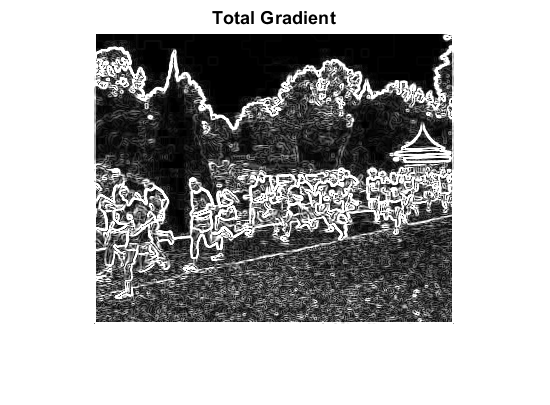

E = sqrt(E); 
imshow(uint8(E)), title("Total Gradient");

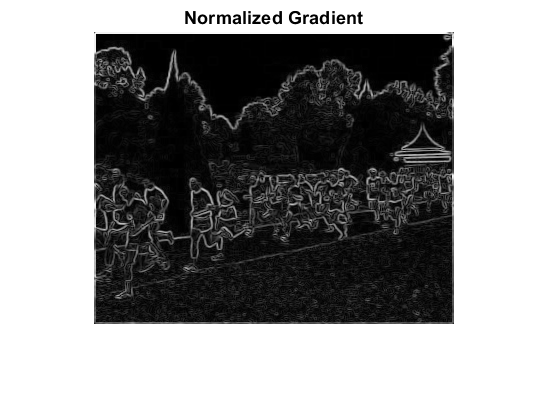

E = (E - min(E(:))) / (max(E(:)) - min(E(:))) * 255;
imshow(uint8(E)), title("Normalized Gradient");

As stated above, Sobel kernel output magnitude of **images gradient projected onto a specific direction**. Thus, the sum of square is the **squared magnitude of gradient**. However, in the **original **Canny algorithm, square root of E and an orientation map $\Theta = atan({G_y\over{G_x}})$ is used. *Thus I will use the ****magnitude of gradient (e.g: square root of sum square), then normalized the result by a MinMaxScaler (e.g: max value is 255)  ****for this experiment. The square root gives much better result and MinMaxScaler is to reduce noisy pattern due to automated clamping by MatLab.*

*As expected, this can display diagonal edges, details and noise level is acceptable.*

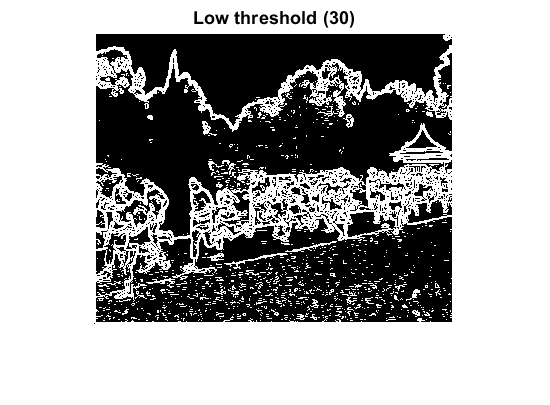

% Part D: Simple thresholding
t = [30, 90, 150];
Et = E>t(1); imshow(Et), title("Low threshold (30)");

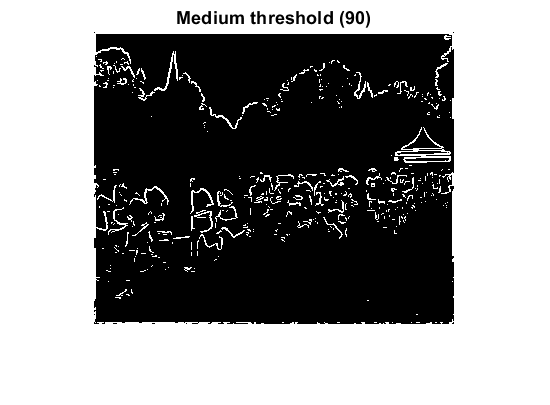

Et = E>t(2); imshow(Et), title("Medium threshold (90)");

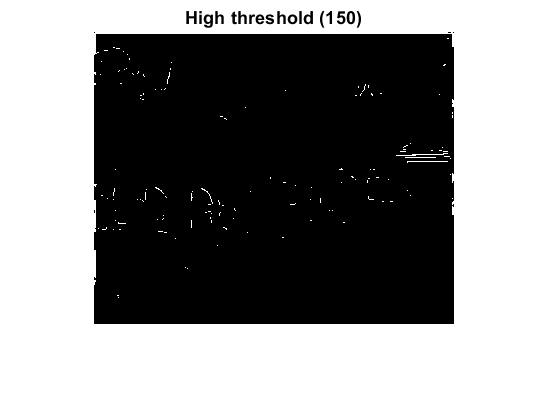

Et = E>t(3); imshow(Et), title("High threshold (150)");

As aboved, images is normalized to be in range [0, 255]. Level of thresholding are: **30 = low**, **90 = medium**, **150 = high.** Low level is too noisy while high level filter out most of image details, thus medium thresholding is preferred. Nevertheless, this customized thresholding allow practitioner to extract and choose level detailedness based on preference or specific use case. (e.g: set high threshold if want to select sharp edge, low threshold if want to see every possible edges).

However, simple thresholding produce a binary image, thus resultant images' quality is very limited (in terms of brightness integrity). And to note, a systematic thresholding scheme (Otsu) might obtain a better (balance) result.

% Part E: MatLAB's Canny implementation.
tl = 0.04; th = 0.1; sigma = 1.0;


#### (i) Varying Sigma = [1.0, 3.0, 5.0]

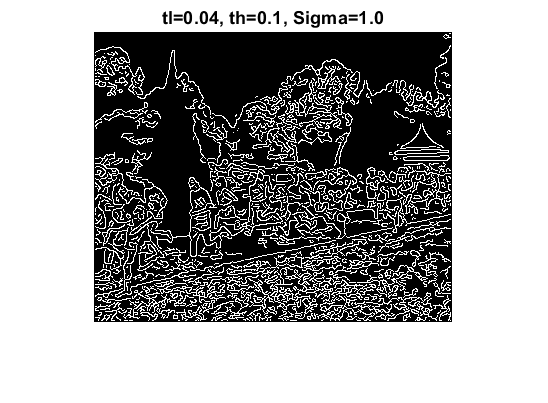

sigmas = [1.0, 3.0, 5.0];
E = edge(I, 'canny', [tl th], sigmas(1));
imshow(E), title("tl=0.04, th=0.1, Sigma=1.0");

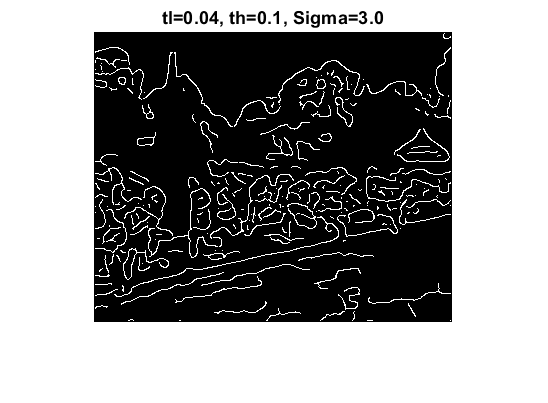

E = edge(I, 'canny', [tl th], sigmas(2));
imshow(E), title("tl=0.04, th=0.1, Sigma=3.0");

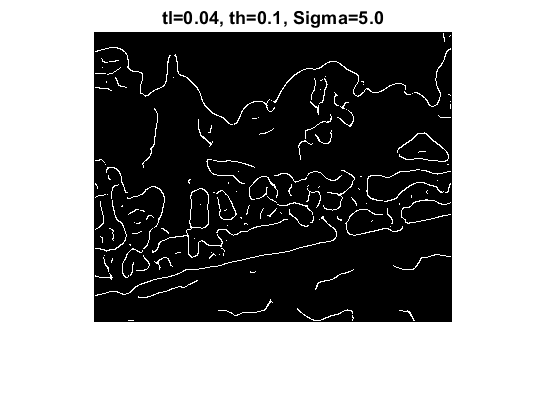

E = edge(I, 'canny', [tl th], sigmas(3));
imshow(E), title("tl=0.04, th=0.1, Sigma=5.0");

As can easily be seen from the experiment, **raising sigma filters out more details** in the resultant image. This is due to the nature of **Gaussian filtering, smaller sigma** mean steeper filter: $\Psi(x,y)= {1\over{2\pi}}*exp(-{{x^2+y^2}\over{2\sigma^2}})$, **steeper filter** $\rightarrow$**better localization,** but** weaker smoothing** effects. Thus, low sigma value ($\sigma=1$) good at localize edgels, keeping much of the details while high sigma ($\sigma=5$) is better at removing noisy edges.

#### (ii) Varying low threshold: th = [1.0, 3.0, 5.0]

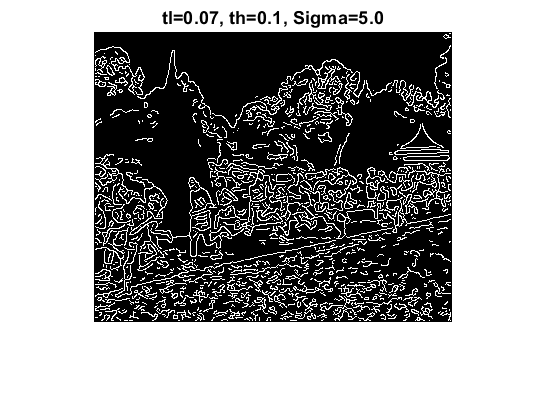

tls = [0.07, 0.04, 0.01];
E = edge(I, 'canny' ,[tls(1) th], sigma);
imshow(E), title("tl=0.07, th=0.1, Sigma=5.0");

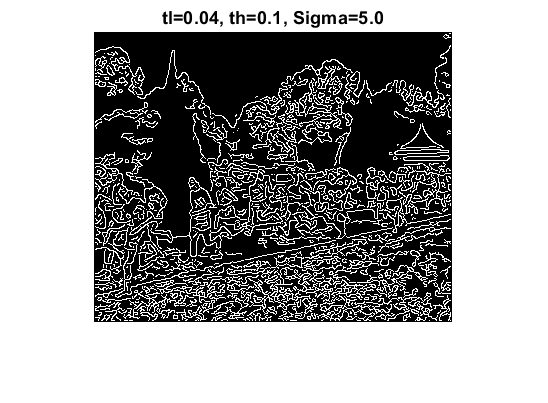

E = edge(I, 'canny' ,[tls(2) th], sigma);
imshow(E), title("tl=0.04, th=0.1, Sigma=5.0");

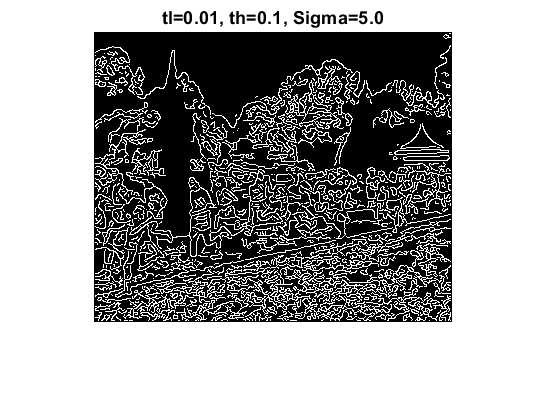

E = edge(I, 'canny' ,[tls(3) th], sigma);
imshow(E), title("tl=0.01, th=0.1, Sigma=5.0");

In Canny Edge detection algorithm,** hysteresis thresholding** is performed by selecting **tl** and **th, **then value above **th **is kept, below **tl** is discarded, between **tl **and **th **is decided to whether be kept or discarded by neighborhood voting (as in Ising model). So it is intuitively easy to see **lowering tl** will result in **more details** are kept, as we expected from the experiment above.

## Part 2: LINE DETECTION

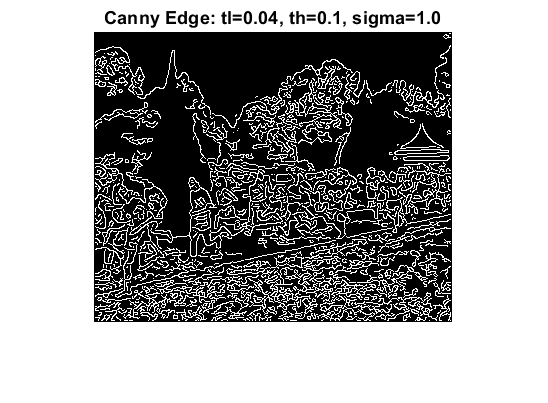

% Part A: Read in -> Canny EDGE.
P = imread('images/maccropped.jpg');
I = rgb2gray(P);
tl = 0.04; th = 0.1; sigma = 1.0;
E = edge(I, 'canny', [tl th], sigma);
imshow(E), title("Canny Edge: tl=0.04, th=0.1, sigma=1.0")

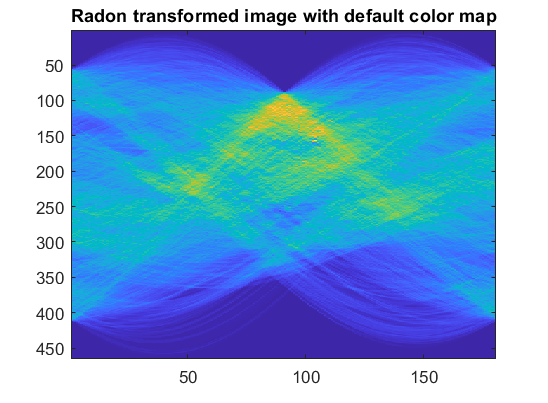

% Part B: Radon transform (Hough binary equivalent)
[R, xp] = radon(E, 0:179);
imagesc(uint8(R));
colormap('default'), title("Radon transformed image with default color map");

Here instead of Hough transform, we use Radon transform, which is a discrete equivalent relation because:

- Recall **Hough transform** and its inverse move back and forth 2 spaces: $(\rho, \ \theta) \leftrightarrow (x,\ y)$ by the relation: $\rho = x \cdot cos(\theta) + y \cdot \sin(\theta)$. That is, a **line in **$(x,\ y)$ corresponding to a** point in **$(\rho,\ \theta)$ while a **wave in **$(\rho,\ \theta)$ is a **point in **$(x,\ y)$. 

- Now the **Radon transform **defined by: 

### 
$$R_{[s,\ \alpha]} = \int_{-\infty}^{\infty} I_{[z \cdot sin(\alpha) + s \cdot cos(\alpha),\ z \cdot cos(\alpha) - s \cdot sin(\alpha)]} \,dz \]$$


Parameters are defined accroding to the picture below and this can be seen as a projections of 2-D bounded function onto a line.  

- **R: **the resultant Radon transform, $s,\ \alpha,\ z$ are defined as in the figure. 

- **I: **2-D function to be transformed, our image in this case (denoted $f(x, y)$ in the figure).

 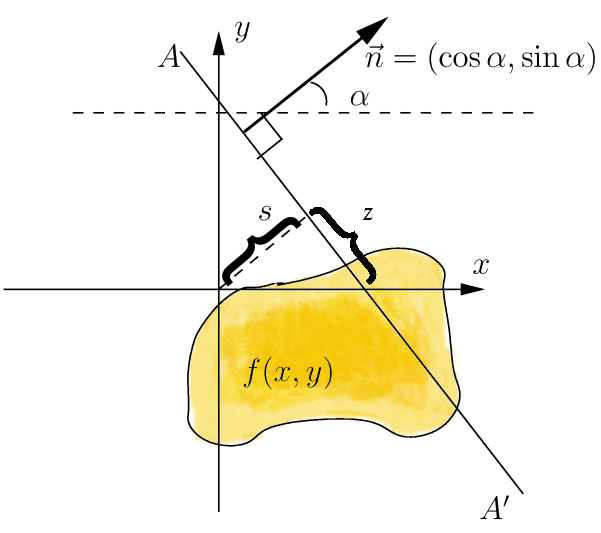

([Image from Wikipedia/Radon_transform](https://en.wikipedia.org/wiki/Radon_transform#/media/File:Radon_transform.png))

In the case of binary image, Radon transformation become **discrete** and thus by **interchanging **$(s,\ \alpha)$** by **$(\rho,\ \theta)$, Radon become Hough transform (e.g: intensity in $(\rho,\ \theta)$is weighted sum of line passing through it in $(x,\ y)$). A line in $(x,\ y)$ can be obtained via inverse transformation defined exactly as Hough transform.

The main different between Radon and Hough transform come from $^{[1]}$:

- **Radon transform:** use a projection integral to **calculate** the characteristic function of a random variable (as the Fourier transform of its probability density function (PDF)) $\longrightarrow$ **mathematically rigorous**, **easily extensible** to higher dimension objects or to complex space (Penrose transform), **well defined for continous function **that satisfy a set of regularity conditions.

- **Hough transform:** obtain the characteristic function by **generating** a random sequence (thus **discrete**), then use emprical histogram binning to obtain PDF.

In conclusion, Hough transform is an **empirical, discretized **version of Radon transform. Though the later is more mathematically rigorous, Hough transform is much faster in a practical settings (use for low computational capacity devices or when fps requirement is high).

% Part C: Pixel with maximum value.
[radius, theta] = find(ismember(R, max(R(:))))

radius = 157

theta = 104


% Part D: Polar to Cartesian 

Conversion from Polar to Cartesian coordinate is performed via: $[x,\ y] = [\rho \cdot cos(\theta),\ \rho \cdot \sin(\theta)]$ (MatLAB's` pol2cart() `function).

theta = 103; % since theta is 0-indexed
radius = xp(157); % x is 1-indexed.
[A, B] = pol2cart(theta*pi/180, radius);
B = -B; % since y-axis is reversed.

To derive C, keep in mind that Radon transformation (or Hough) is done with respect to an origin at the centre of the image, while this origin is at top-left corner in the original image. Thus, A and B (the center) is shifted by $358/2=179,\ 290/2=145$, formula for C is in the code below. 

C = A*(A+179) + B*(B+145);

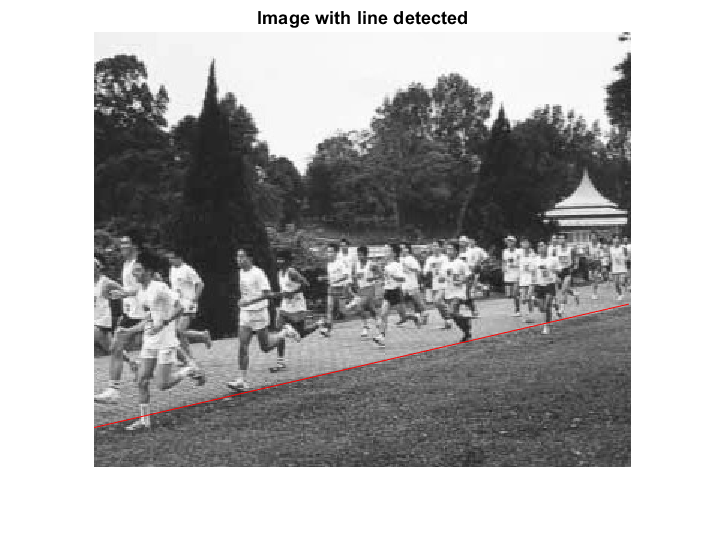

% Part E: Solve for line equation
xl = 0; xr = 357; % image size is 290 x 358.
yl = (C - A * xl) / B;
yr = (C - A * xr) / B;

% part F: Show the image with line
imshow(I, 'InitialMagnification', 150), line([xl xr], [yl yr], 'Color','r'), title("Image with line detected");

The line calculated from our algorithm almost perfectly match up with the edge of the running path. This suggest edgel strength is high, and our algorithm did well in identifying this edge.

Nevertheless, this is not the best achievable result as there are various possible source of errors in calculation steps:

- Since image is** preprocess by Canny** Edge detection, inappropriate hyper-parameter selection directly affect overall result. Hence, improvement can be made by varying hyper parameter or directly improve the Canny itself (change smoothing [Gaussian => adaptive filter], convolution filter [Sobel => Prewitt, Scharr, Cross], all are selected based on image specification).  

- **Non-locality** of peek in Hough **transformed domain**$(\rho,\ \theta)$. This can be improved by **select a set of lines near maxima** (3 to 5 points in transformed domain), and choose the best among them (rank by preference or a designed heuristic function)  

## Part 3: STEREO VISION

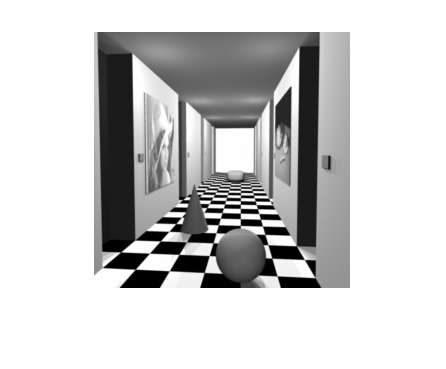

% Part A: define the disparity map algorithm

% b
l = imread('images/corridorl.jpg'); 
l = rgb2gray(l);
imshow(l);

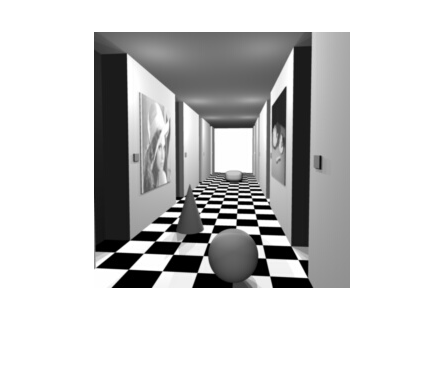

r = imread('images/corridorr.jpg');
r = rgb2gray(r);
imshow(r);

% part C:
D = map(l, r, 11, 11);

Unrecognized function or variable 'map'.

imshow(D,[-15 15]);
res = imread('image/corridor_disp.jpg');
imshow(res);

% Part D:
l = imread('image/triclopsi2l.jpg'); 
l = rgb2gray(l);
imshow(l);
r = imread('image/triclopsi2r.jpg');
r = rgb2gray(r);
imshow(r);

D = map(l, r, 11, 11);
imshow(D,[-15 15]);
res = imread('image/triclopsid.jpg');
imshow(res);


Reference: 

1. [Stack Exchange discussion: /a/472](https://dsp.stackexchange.com/a/472)

2. 